# Add a Slide to a Presentation

To add a slide to a presentation, use the `add` method of the `mlreportgen.ppt.Presentation` object. The `add` method returns an `mlreportgen.ppt.Slide` object. Use the `replace` method of the `Slide` object to replace content placeholders with your content.

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create and open a presentation.

ppt = Presentation("myPresentation.pptx");
open(ppt);

Add a slide that has a `Title and Table` layout.

slide = add(ppt,"Title and Table");

Replace the `Title` placeholder in the slide with the title text.

replace(slide,"Title","magic(4)");

Replace the `Table` placeholder in the slide with a table.

tbl = Table(magic(4));
replace(slide,"Table",tbl);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the generated presentation:

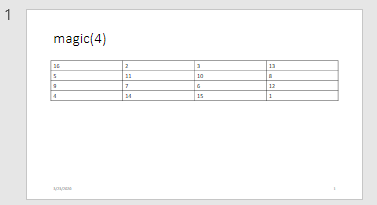

*Copyright 2020 The MathWorks, Inc.*